%Fecha de actualizacion 14/abril/2023
clc
clear all
close all

Portada

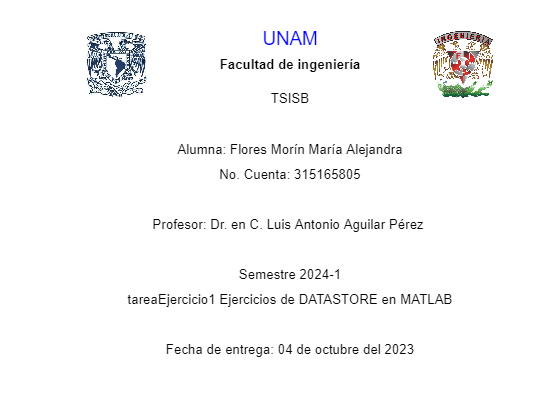

figure(1);
% tamaño de la figura
%  set(gcf, 'Position', [100, 100, 800, 600]);
tamano_letra=10;
% Cargar y mostrar la primera imagen
img1 = imread('UNAMlogo.png');  % Reemplaza 'imagen1.jpg' con el nombre de tu primera imagen
subplot(4, 4, 1);  % Divide la figura en 1 fila y 2 columnas, y selecciona la primera posición
imshow(img1);

% Cargar y mostrar la segunda imagen
img2 = imread('FIlogo.jpg');  % Reemplaza 'imagen2.jpg' con el nombre de tu segunda imagen
subplot(4, 4, 4);  % Selecciona la segunda posición
imshow(img2);

% Agregar texto a un subplot específico (por ejemplo, el subplot 8)
subplot(4, 4, [2,3]); 
text(0.5, 0.9, 'UNAM', 'FontSize', 14,'HorizontalAlignment', 'center','Color','b');
text(0.5, 0.5, 'Facultad de ingeniería', 'FontSize', tamano_letra, 'FontWeight', 'bold', 'HorizontalAlignment', 'center');
text(0.5, 0.0, 'TSISB', 'FontSize', tamano_letra,'HorizontalAlignment', 'center');
axis off
subplot(4, 4, [5, 6, 7, 8, 9, 10, 11, 12, 13, 14, 15, 16]); 
text(0.5, 0.9, 'Alumna: Flores Morín María Alejandra', 'FontSize', tamano_letra,'HorizontalAlignment', 'center');
text(0.5, 0.8, 'No. Cuenta: 315165805', 'FontSize', tamano_letra,'HorizontalAlignment', 'center');
text(0.5, 0.6, 'Profesor: Dr. en C. Luis Antonio Aguilar Pérez ', 'FontSize', tamano_letra,'HorizontalAlignment', 'center');
text(0.5, 0.4, 'Semestre 2024-1', 'FontSize', tamano_letra,'HorizontalAlignment', 'center');
text(0.5, 0.3, 'tareaEjercicio1 Ejercicios de DATASTORE en MATLAB', 'FontSize', tamano_letra,'HorizontalAlignment', 'center');
text(0.5, 0.1, 'Fecha de entrega: 04 de octubre del 2023', 'FontSize', tamano_letra,'HorizontalAlignment', 'center');
axis off

# Análisis exploratorio de una base de datos

%****
%En este ejercicio solo estaremos trabajando con un archivo
%contenido dentro del datastore
%****

%%%
%Creacion de directorio de trabajo
%rootFolder = 'D:\TSISB_IA';
rootFolder ='C:\Users\puma_\Documents\TSISB_IA';
workingFolder = 'practica_3';
tempFolder = 'temp';
savePath = fullfile(rootFolder,workingFolder);
saveTempPath = fullfile(rootFolder,workingFolder,tempFolder);

prefix = ['\' 'heart'];
sufix = '.csv';
newName = [prefix, sufix];

%Despues de correr esta celda una vez, crea un bloque de comentarios a partir de esta linea

if ~exist(savePath,'dir')
    [status, message, ~] = mkdir(savePath);
    if status == 0
        disp(message)
    end
end

if ~exist(saveTempPath,'dir')
    [status, message, ~] = mkdir(saveTempPath);
    if status == 0
        disp(message)
    end
end

%%%
%Organizacion y copia de archivos
[fileName, pathFileName] = uigetfile('C:\','*.txt' );

if isequal(fileName,0)
    disp('Se canceló la busqueda de archivos');
else
    disp(['El usuario seleccionó el archivo ', fullfile(pathFileName,fileName)]);
    [status, message, ~] = copyfile([pathFileName,fileName],[saveTempPath,newName]);
    prefix = ['heart'];
    sufix = '.csv';
    newName = [prefix, sufix];
    if status == 0
        disp(message)
    else
        disp(['El cual se movio a la dirección ', fullfile(saveTempPath)]);
    end
end

El usuario seleccionó el archivo C:\Users\puma_\Documents\TSISB_IA\practica_3\heart.csv


El cual se movio a la dirección C:\Users\puma_\Documents\TSISB_IA\practica_3\temp


%}

## Análisis exploratorio de datos

%Se determina la direccion de los archivos que integran el "Datastore"
archivoCSV = "heart.csv"

archivoCSV = "heart.csv"

%Visualización rápida de las primeras lineas del archivo de texto
%Como solo es un archivo se puede utilizar el comando dbtype
dbtype("heart.csv",'1:5')

1     age,sex,cp,trestbps,chol,fbs,restecg,thalach,exang,oldpeak,slope,ca,thal,target
2     52,1,0,125,212,0,1,168,0,1,2,2,3,0
3     53,1,0,140,203,1,0,155,1,3.1,0,0,3,0
4     70,1,0,145,174,0,1,125,1,2.6,0,0,3,0
5     61,1,0,148,203,0,1,161,0,0,2,1,3,0


%Visualizacion general de las opciones de importacion de los archivos
%dentro del datastore
opts = detectImportOptions("heart.csv")

opts =   DelimitedTextImportOptions with properties:

   Format Properties:
                    Delimiter: {','}
                   Whitespace: '\b\t '
                   LineEnding: {'\n'  '\r'  '\r\n'}
                 CommentStyle: {}
    ConsecutiveDelimitersRule: 'split'
        LeadingDelimitersRule: 'keep'
       TrailingDelimitersRule: 'ignore'
                EmptyLineRule: 'skip'
                     Encoding: 'UTF-8'

   Replacement Properties:
                  MissingRule: 'fill'
              ImportErrorRule: 'fill'
             ExtraColumnsRule: 'addvars'

   Variable Import Properties: Set types by name using setvartype
                VariableNames: {'age', 'sex', 'cp' ... and 11 more}
                VariableTypes: {'double', 'double', 'double' ... and 11 more}
        SelectedVariableName

%Visualizacion de los nombres y tipo de variables de las columnas
disp([opts.VariableNames' opts.VariableTypes'])

    {'age'     }    {'double'}
    {'sex'     }    {'double'}
    {'cp'      }    {'double'}
    {'trestbps'}    {'double'}
    {'chol'    }    {'double'}
    {'fbs'     }    {'double'}
    {'restecg' }    {'double'}
    {'thalach' }    {'double'}
    {'exang'   }    {'double'}
    {'oldpeak' }    {'double'}
    {'slope'   }    {'double'}
    {'ca'      }    {'double'}
    {'thal'    }    {'double'}
    {'target'  }    {'double'}



%Desde la version 2019, los nombres de las variables pueden incluir
%cualquier tipo de simbolos, ademas de no necesariamente comenzar solo
%con letras, por lo que matlab requiere el Flag "preserve" para considerar
%esta opción
opts.VariableNamingRule='preserve';

## Tabla de resumen de los datos

%Asignacion a una variable particular
values=opts.VariableNames;
%Modificacion como si fuera un indexado de valores clásico
newValues={'Edad','Sexo','Tipo Dolor','Presión arterial en reposo [mmHg]','Colesterol sérico [mg/dl]','Azúcar en sangre (ayunas) [mg/dl]','Resultados ECG (0, 1, 2)','Máx Fr cardíaca[latidos/min]','Angina inducida por el ejercicio','Depresión del ST por ejercicio','Pendiente segmento ST del máx ejercicio','No de vasos principales coloreados por fluoroscopia','Thal','Enfermedad cardíaca'};
opts.VariableNames = newValues;
Heart_1 = readtable(archivoCSV,opts);
head(Heart_1)

    Edad    Sexo    Tipo Dolor    Presión arterial en reposo [mmHg]    Colesterol sérico [mg/dl]    Azúcar en sangre (ayunas) [mg/dl]    Resultados ECG (0, 1, 2)    Máx Fr cardíaca[latidos/min]    Angina inducida por el ejercicio    Depresión del ST por ejercicio    Pendiente segmento ST del máx ejercicio    No de vasos principales coloreados por fluoroscopia    Thal    Enfermedad cardíaca
    ____    ____    __________    _________________________________    _________________________    _________________________________    ________________________    ____________________________    ____________________________

%Número de participantes:
PersonasEstudio=nnz(Heart_1.("Edad"));
disp("Participantes del estudio: "+PersonasEstudio);

Participantes del estudio: 1025


%Cuántas muejeres y hombres hay
Genero = categorical(Heart_1.Sexo);
grpCatGenero = categories(Genero)

grpCatGenero = 2×1 cell array
    {'0'}
    {'1'}


nuevosGeneros = {'Mujeres',...
                'Hombres'};
nuevoGenero = renamecats(Genero,nuevosGeneros);
summary(nuevoGenero)

     Mujeres      312 
     Hombres      713 




tbl=tabulate(nuevoGenero)

tbl = 2×3 cell array
    {'Mujeres'}    {[312]}    {[30.4390]}
    {'Hombres'}    {[713]}    {[69.5610]}


t = cell2table(tbl,'VariableNames', ...
    {'Value','Count','Percent'});
t.Value = categorical(t.Value)

t = 2×3 table
     Value     Count    Percent
    _______    _____    _______

    Mujeres     312     30.439 
    Hombres     713     69.561 


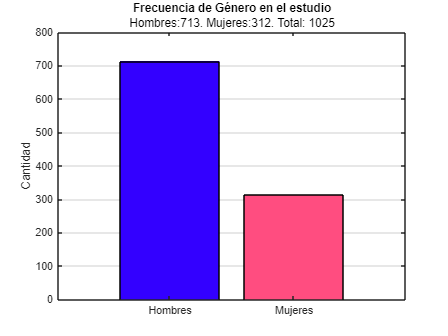

figure
colors = [0.2 0 1;1 0.3 0.5];
BarrasGenero=bar(t.Value,t.Count,"FaceColor","flat","CData",colors);
ylabel('Cantidad')
set(gca,"XGrid","off","YGrid","on")
title("Frecuencia de Género en el estudio","Hombres:"+t.Count(2,1)+". Mujeres:"+t.Count(1,1)+". Total: "+(t.Count(2,1)+t.Count(1,1)))

clear ylim
% ylim([0 100])

t = cell2table(tbl,'VariableNames', ...
    {'Value','Count','Percent'});
t.Value = categorical(t.Value)

t = 2×3 table
     Value     Count    Percent
    _______    _____    _______

    Mujeres     312     30.439 
    Hombres     713     69.561 


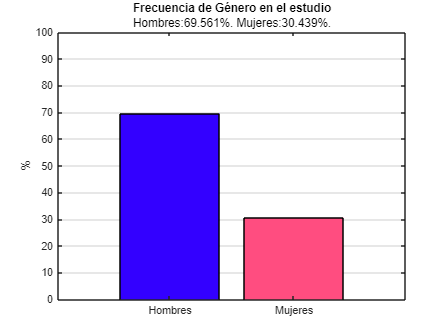

close all
figure
colors = [0.2 0 1;1 0.3 0.5];
BarrasGenero=bar(t.Value,t.Percent,"FaceColor","flat","CData",colors);
ylabel('%')
set(gca,"XGrid","off","YGrid","on")
title("Frecuencia de Género en el estudio","Hombres:"+t.Percent(2,1)+"%. Mujeres:"+t.Percent(1,1)+"%.")
clear ylim
ylim([0 100])

## Tabla de frecuencias

### Principales signos para diagnosticar Enfermedad Cardiaca.

Heart_1 = readtable(archivoCSV,opts);
%Eliminacion de caracteristicas de la tabla
Heart_2 = removevars(Heart_1,{'Tipo Dolor','Resultados ECG (0, 1, 2)','Pendiente segmento ST del máx ejercicio','No de vasos principales coloreados por fluoroscopia','Thal'});
head(Heart_2)

    Edad    Sexo    Presión arterial en reposo [mmHg]    Colesterol sérico [mg/dl]    Azúcar en sangre (ayunas) [mg/dl]    Máx Fr cardíaca[latidos/min]    Angina inducida por el ejercicio    Depresión del ST por ejercicio    Enfermedad cardíaca
    ____    ____    _________________________________    _________________________    _________________________________    ____________________________    ________________________________    ______________________________    ___________________

     52      1                     125                              212                               0                                168                                0                                

Edad = categorical(Heart_2.Edad);
% summary(Edad)

## Tabla personas Enfermedad Cardiaca

%Filtro para personas con Enfermedad Cardiaca
filtro = (Heart_2.("Enfermedad cardíaca") == 1);
Heart_2_Enfermos = Heart_2(filtro, :)

Heart_2_Enfermos = 526×9 table
    Edad    Sexo    Presión arterial en reposo [mmHg]    Colesterol sérico [mg/dl]    Azúcar en sangre (ayunas) [mg/dl]    Máx Fr cardíaca[latidos/min]    Angina inducida por el ejercicio    Depresión del ST por ejercicio    Enfermedad cardíaca
    ____    ____    _________________________________    _________________________    _________________________________    ____________________________    ________________________________    ______________________________    ___________________

     58      0                     100                              248                               0                                122                                0 


%Cambiar genero
Genero = categorical(Heart_2_Enfermos.Sexo);
grpCatGenero = categories(Genero);
nuevosGeneros = {'Mujeres',...
                'Hombres'};
nuevoGenero = renamecats(Genero,nuevosGeneros);
summary(nuevoGenero)

     Mujeres      226 
     Hombres      300 


FrecuenciasGeneroEnfermos=tabulate(nuevoGenero)

FrecuenciasGeneroEnfermos = 2×3 cell array
    {'Mujeres'}    {[226]}    {[42.9658]}
    {'Hombres'}    {[300]}    {[57.0342]}


e = cell2table(FrecuenciasGeneroEnfermos,'VariableNames', ...
    {'Value','Count','Percent'});
e.Value = categorical(e.Value)

e = 2×3 table
     Value     Count    Percent
    _______    _____    _______

    Mujeres     226     42.966 
    Hombres     300     57.034 


% figure
% BarrasGenero=bar(t.Value,t.Percent);
% ylabel('Frecuencia %')
% set(gca,"XGrid","off","YGrid","on")
% title("Frecuencia de género con enfermedades cardiacas")

## frecuencias de sintomas en enfermos

%Cuantas personas enfermas hay TOTAL
PersonasEnfermasTotal=sum(Heart_2_Enfermos.("Enfermedad cardíaca"));

### Tabla frecuencias por sintomas

%Principales Signos Enfermedad Cardiaca PA
filtro = (Heart_2_Enfermos.("Presión arterial en reposo [mmHg]") >= 140);
Heart_2_Enfermos_PA = Heart_2_Enfermos(filtro, :);
PersonasSanasConSintoma=nnz(Heart_2_Enfermos_PA.("Presión arterial en reposo [mmHg]"));
FrecuenciaSintoma=(PersonasSanasConSintoma/PersonasEnfermasTotal*100);
% disp("Frecuencia: "+FrecuenciaSintoma+"%")
Sintoma="Presión Arterial alta";
tablaFrePA = table(Sintoma,PersonasSanasConSintoma,FrecuenciaSintoma);
%Principales Signos Enfermedad Cardiaca Colesterol Alto:
filtro = (Heart_2_Enfermos.("Colesterol sérico [mg/dl]") >= 200);
Heart_2_Enfermos_Colesterol = Heart_2_Enfermos(filtro, :);
PersonasSanasConSintoma=nnz(Heart_2_Enfermos_Colesterol.("Colesterol sérico [mg/dl]"));
FrecuenciaSintoma=(PersonasSanasConSintoma/PersonasEnfermasTotal*100);
% disp("Frecuencia: "+FrecuenciaSintoma+"%")
Sintoma="Colesterol Alto";
tablaFreColes = table(Sintoma,PersonasSanasConSintoma,FrecuenciaSintoma);
%Principales Signos Enfermedad Cardiaca Frecuencia Cardiaca
filtro = (Heart_2_Enfermos.("Máx Fr cardíaca[latidos/min]") >= 100);
Heart_2_Enfermos_FrMax = Heart_2_Enfermos(filtro, :);
PersonasSanasConSintoma=nnz(Heart_2_Enfermos_FrMax.("Máx Fr cardíaca[latidos/min]"));
FrecuenciaSintoma=(PersonasSanasConSintoma/PersonasEnfermasTotal*100);
% disp("Frecuencia: "+FrecuenciaSintoma+"%");
Sintoma="Frecuencia Cardíaca Alta";
tablaFreMax = table(Sintoma,PersonasSanasConSintoma,FrecuenciaSintoma);
%Principales Signos Enfermedad Cardiaca Diabetes :D 1= Presentaron niveles
%mayor a 120
filtro = (Heart_2_Enfermos.("Azúcar en sangre (ayunas) [mg/dl]") == 1);
Heart_2_Enfermos_Diabetes = Heart_2_Enfermos(filtro, :);
PersonasSanasConSintoma=nnz(Heart_2_Enfermos_Diabetes.("Azúcar en sangre (ayunas) [mg/dl]"));
FrecuenciaSintoma=(PersonasSanasConSintoma/PersonasEnfermasTotal*100);
% disp("Frecuencia: "+FrecuenciaSintoma+"%");
Sintoma="Diabetes";
tablaFreDiabetes = table(Sintoma,PersonasSanasConSintoma,FrecuenciaSintoma);

## Tabla de todos los sintomas en enfermos

TablaSintomasPE = [tablaFrePA;tablaFreColes;tablaFreMax;tablaFreDiabetes]

TablaSintomasPE = 4×3 table
             Sintoma              PersonasSanasConSintoma    FrecuenciaSintoma
    __________________________    _______________________    _________________

    "Presión Arterial alta"                 137                   26.046      
    "Colesterol Alto"                       427                   81.179      
    "Frecuencia Cardíaca Alta"              523                    99.43      
    "Diabetes"                               71                   13.498      


## frecuencias de sintomas en sanos

%Cuantas personas sanas hay TOTAL
close all
%Filtro para personas 'Sanas'
filtro = (Heart_2.("Enfermedad cardíaca") == 0);
Heart_2_Sanas = Heart_2(filtro, :);
PersonasSanasTotal=nnz(Heart_2_Sanas.Edad);

### Tabla frecuencias por sintomas

%Principales Signos Enfermedad Cardiaca PA
filtro = (Heart_2_Sanas.("Presión arterial en reposo [mmHg]") >= 140);
Heart_2_Sanas_PA = Heart_2_Sanas(filtro, :);
PersonasSanasConSintoma=nnz(Heart_2_Enfermos_PA.("Presión arterial en reposo [mmHg]"));
FrecuenciaSintoma=(PersonasSanasConSintoma/PersonasSanasTotal*100);
% disp("Frecuencia: "+FrecuenciaSintoma+"%")
Sintoma="Presión Arterial alta";
tablaSanasFrePA = table(Sintoma,PersonasSanasConSintoma,FrecuenciaSintoma);
%Principales Signos Enfermedad Cardiaca Colesterol Alto:
filtro = (Heart_2_Sanas.("Colesterol sérico [mg/dl]") >= 200);
Heart_2_Sanas_Colesterol = Heart_2_Sanas(filtro, :);
PersonasSanasConSintoma=nnz(Heart_2_Sanas_Colesterol.("Colesterol sérico [mg/dl]"));
FrecuenciaSintoma=(PersonasSanasConSintoma/PersonasSanasTotal*100);
% disp("Frecuencia: "+FrecuenciaColesterol+"%");
Sintoma="Colesterol Alto";
tablaSanasFreColes = table(Sintoma,PersonasSanasConSintoma,FrecuenciaSintoma);
%Principales Signos Enfermedad Cardiaca Frecuencia Cardiaca
filtro = (Heart_2_Sanas.("Máx Fr cardíaca[latidos/min]") >= 100);
Heart_2_Sanas_FrMax = Heart_2_Sanas(filtro, :);
PersonasSanasConSintoma=nnz(Heart_2_Sanas_FrMax.("Máx Fr cardíaca[latidos/min]"));
FrecuenciaFrMax=(PersonasSanasConSintoma/PersonasSanasTotal*100);
% disp("Frecuencia: "+FrecuenciaSintoma+"%");
Sintoma="Frecuencia Cardíaca Alta";
tablaSanasFreMax = table(Sintoma,PersonasSanasConSintoma,FrecuenciaSintoma);
%Principales Signos Enfermedad Cardiaca Diabetes :D 1= Presentaron niveles
%mayor a 120
filtro = (Heart_2_Sanas.("Azúcar en sangre (ayunas) [mg/dl]") == 1);
Heart_2_Sanas_Diabetes = Heart_2_Sanas(filtro, :);
PersonasSanasConSintoma=nnz(Heart_2_Sanas_Diabetes.("Azúcar en sangre (ayunas) [mg/dl]"));
FrecuenciaSintoma=(PersonasSanasConSintoma/PersonasSanasTotal*100);
% disp("Frecuencia: "+FrecuenciaSintoma+"%");
Sintoma="Diabetes";
tablaSanasFreDiabetes = table(Sintoma,PersonasSanasConSintoma,FrecuenciaSintoma);

## Tabla de todos los sintomas en sanos

TablaSintomasPS = [tablaSanasFrePA;tablaSanasFreColes;tablaSanasFreMax;tablaSanasFreDiabetes]

TablaSintomasPS = 4×3 table
             Sintoma              PersonasSanasConSintoma    FrecuenciaSintoma
    __________________________    _______________________    _________________

    "Presión Arterial alta"                 137                   27.455      
    "Colesterol Alto"                       429                   85.972      
    "Frecuencia Cardíaca Alta"              474                   85.972      
    "Diabetes"                               82                   16.433      


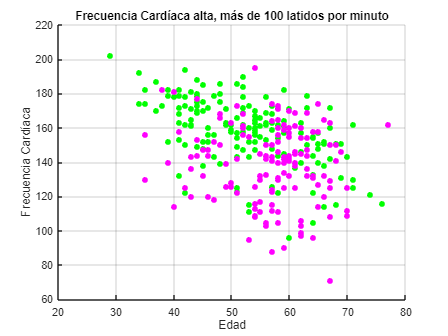

close all
sz = 30;

scatter(Heart_2_Enfermos.Edad,Heart_2_Enfermos.("Máx Fr cardíaca[latidos/min]"),sz,'green','filled')

hold on
scatter(Heart_2_Sanas.Edad,Heart_2_Sanas.("Máx Fr cardíaca[latidos/min]"),sz,'magenta','filled')

grid on
xlabel("Edad")
ylabel("Frecuencia Cardíaca")

title("Frecuencia Cardíaca alta, más de 100 latidos por minuto")

## Histograma frecuencias de Sintomas

TablaSintomasPE

TablaSintomasPE = 4×3 table
             Sintoma              PersonasSanasConSintoma    FrecuenciaSintoma
    __________________________    _______________________    _________________

    "Presión Arterial alta"                 137                   26.046      
    "Colesterol Alto"                       427                   81.179      
    "Frecuencia Cardíaca Alta"              523                    99.43      
    "Diabetes"                               71                   13.498      


TablaSintomasPS 

TablaSintomasPS = 4×3 table
             Sintoma              PersonasSanasConSintoma    FrecuenciaSintoma
    __________________________    _______________________    _________________

    "Presión Arterial alta"                 137                   27.455      
    "Colesterol Alto"                       429                   85.972      
    "Frecuencia Cardíaca Alta"              474                   85.972      
    "Diabetes"                               82                   16.433      


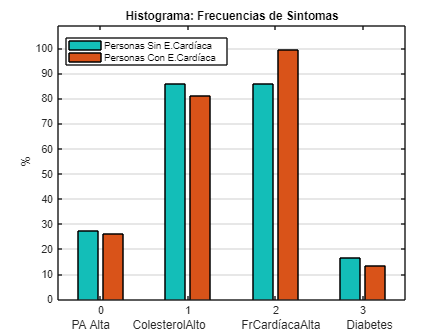

close all
figure
subplot(1,1,1)
TablaSintomasPS.FrecuenciaSintoma(1);
x=[0;1;2;3];
y=[TablaSintomasPS.FrecuenciaSintoma(1) TablaSintomasPE.FrecuenciaSintoma(1);TablaSintomasPS.FrecuenciaSintoma(2) TablaSintomasPE.FrecuenciaSintoma(2);TablaSintomasPS.FrecuenciaSintoma(3) TablaSintomasPE.FrecuenciaSintoma(3);TablaSintomasPS.FrecuenciaSintoma(4) TablaSintomasPE.FrecuenciaSintoma(4)];
BarrasSintomas=bar(x,y,'FaceColor','flat');
for k = 1:size(1,3)
    BarrasSintomas(k).CData = k;
end
ylabel('%')
set(gca,"XGrid","off","YGrid","on")
title("Histograma: Frecuencias de Sintomas");
clear ylim
ylim([0 109])
legend(["Personas Sin E.Cardíaca","Personas Con E.Cardíaca"])
xlabel("PA Alta       ColesterolAlto           FrCardíacaAlta        Diabetes")
legend("Position", [0.15777,0.80674,0.34107,0.082143])

%Agrupar por Edad y Sexo
Heart_3_Enfermos = groupsummary(Heart_2_Enfermos,["Edad","Sexo"],"mean")

Heart_3_Enfermos = 68×10 table
    Edad    Sexo    GroupCount    mean_Presión arterial en reposo [mmHg]    mean_Colesterol sérico [mg/dl]    mean_Azúcar en sangre (ayunas) [mg/dl]    mean_Máx Fr cardíaca[latidos/min]    mean_Angina inducida por el ejercicio    mean_Depresión del ST por ejercicio    mean_Enfermedad cardíaca
    ____    ____    __________    ______________________________________    ______________________________    ______________________________________    _________________________________    _____________________________________    ___________________________________    ________________________

     29      1           4              

% figure(1)
% subplot(1,1,1)
% Img3=histogram(Heart_3_Enfermos.Edad,min(Heart_2.Edad):6:max(Heart_2.Edad));
% Img3.FaceColor = [0.5 0.99 0.5];
% title('Histograma de Personas Enfermas por edad');

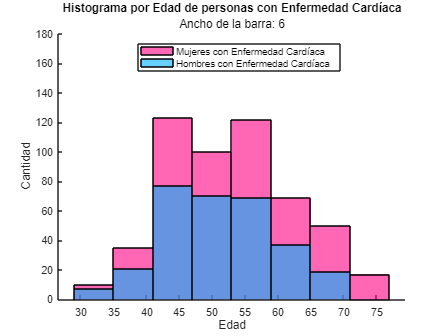

close all

%Histogramas
%Histograma Todos por edad
figure(1)
hold on
subplot(1,1,1)
Img3=histogram(Heart_2_Enfermos.Edad,min(Heart_2.Edad):6:max(Heart_2.Edad));
Img3.FaceColor = [1 0 0.5];
% Histograma Mujeres por edad
%Filtro para MUJERES con Enfermedad Cardiaca
filtro = (Heart_2_Enfermos.("Sexo") == 1);
Heart_3_Enfermos_Mujeres = Heart_2_Enfermos(filtro, :);
Img5=histogram(Heart_3_Enfermos_Mujeres.Edad,min(Heart_2.Edad):6:max(Heart_2.Edad));

Img5.FaceColor = [0 0.7 1];
title('Histograma por Edad de personas con Enfermedad Cardíaca',"Ancho de la barra: 6");
clear ylim
ylim([0 180])
legend(["Mujeres con Enfermedad Cardíaca","Hombres con Enfermedad Cardíaca"])
xlabel("Edad")
ylabel("Cantidad")
legend("Position", [0.31667,0.79008,0.43571,0.082143])

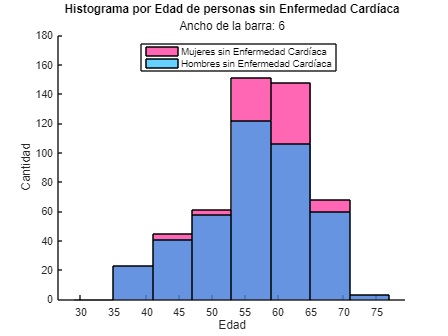

close all
%Histograma TODOS por edad
figure(1)
hold on
subplot(1,1,1)
Img3=histogram(Heart_2_Sanas.Edad,min(Heart_2.Edad):6:max(Heart_2.Edad));
Img3.FaceColor = [1 0 0.5];
%0 - mujer, 1 - hombre
filtro = (Heart_2_Sanas.("Sexo") == 1);
Heart_3_Sanas_Mujeres = Heart_2_Sanas(filtro, :);
Img6=histogram(Heart_3_Sanas_Mujeres.Edad,min(Heart_2.Edad):6:max(Heart_2.Edad));
Img6.FaceColor = [0 0.7 1];
title('Histograma por Edad de personas sin Enfermedad Cardíaca',"Ancho de la barra: 6");
ylim([0, 180]); % Límites del eje y

legend(["Mujeres sin Enfermedad Cardíaca","Hombres sin Enfermedad Cardíaca"])
xlabel("Edad")
ylabel("Cantidad")
legend("Position", [0.31667,0.79008,0.43571,0.082143])

## Tabla personas "Sanas"

close all
%Filtro para personas 'Sanas'
filtro = (Heart_2.("Enfermedad cardíaca") == 0);
Heart_2_Sanas = Heart_2(filtro, :)

Heart_2_Sanas = 499×9 table
    Edad    Sexo    Presión arterial en reposo [mmHg]    Colesterol sérico [mg/dl]    Azúcar en sangre (ayunas) [mg/dl]    Máx Fr cardíaca[latidos/min]    Angina inducida por el ejercicio    Depresión del ST por ejercicio    Enfermedad cardíaca
    ____    ____    _________________________________    _________________________    _________________________________    ____________________________    ________________________________    ______________________________    ___________________

     52      1                     125                              212                               0                                168                                0    

%Cambiar genero
Genero = categorical(Heart_2_Sanas.Sexo);
grpCatGenero = categories(Genero);
nuevosGeneros = {'Mujeres',...
                'Hombres'};
nuevoGenero = renamecats(Genero,nuevosGeneros);
FrecuenciasGeneroSanos=tabulate(nuevoGenero)

FrecuenciasGeneroSanos = 2×3 cell array
    {'Mujeres'}    {[ 86]}    {[17.2345]}
    {'Hombres'}    {[413]}    {[82.7655]}


s = cell2table(FrecuenciasGeneroSanos,'VariableNames', ...
    {'Value','Count','Percent'});
s.Value = categorical(s.Value)

s = 2×3 table
     Value     Count    Percent
    _______    _____    _______

    Mujeres      86     17.234 
    Hombres     413     82.766 



%Agrupar por Edad y Sexo Per
Heart_3_Sanas = groupsummary(Heart_2_Sanas,["Edad","Sexo"],"mean")

Heart_3_Sanas = 48×10 table
    Edad    Sexo    GroupCount    mean_Presión arterial en reposo [mmHg]    mean_Colesterol sérico [mg/dl]    mean_Azúcar en sangre (ayunas) [mg/dl]    mean_Máx Fr cardíaca[latidos/min]    mean_Angina inducida por el ejercicio    mean_Depresión del ST por ejercicio    mean_Enfermedad cardíaca
    ____    ____    __________    ______________________________________    ______________________________    ______________________________________    _________________________________    _____________________________________    ___________________________________    ________________________

     35      1           7                 

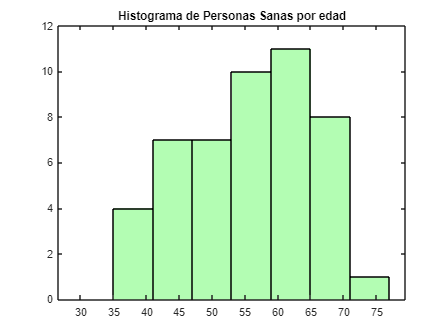

figure(2)
subplot(1,1,1)
Img4=histogram(Heart_3_Sanas.Edad,min(Heart_2.Edad):6:max(Heart_2.Edad));
Img4.FaceColor = [0.5 0.99 0.5];
title('Histograma de Personas Sanas por edad');

## Frecuencias M vs H por Enfermedad y Sanos

% nuevoGenero = renamecats(Genero,nuevosGeneros);

### Enfermos

% FrecuenciasGeneroEnfermos=tabulate(nuevoGenero);
% e = cell2table(FrecuenciasGeneroEnfermos,'VariableNames', ...
%     {'Value','Count','Percent'});
% e.Value = categorical(e.Value)
e

e = 2×3 table
     Value     Count    Percent
    _______    _____    _______

    Mujeres     226     42.966 
    Hombres     300     57.034 


### Sanos

% FrecuenciasGeneroSanos=tabulate(nuevoGenero);
% s = cell2table(FrecuenciasGeneroSanos,'VariableNames', ...
%     {'Value','Count','Percent'});
% s.Value = categorical(s.Value)
s

s = 2×3 table
     Value     Count    Percent
    _______    _____    _______

    Mujeres      86     17.234 
    Hombres     413     82.766 


### Gráfica

%Cuántos sanos y enfermos hay
Estado = categorical(Heart_1.("Enfermedad cardíaca"));
grpCatGenero = categories(Estado);
nuevosEstados = {'No hay enfermedad cardiaca',...
                'Enfermedad cardiaca'};
nuevoEstado = renamecats(Estado,nuevosEstados);
summary(nuevoEstado)

     No hay enfermedad cardiaca      499 
     Enfermedad cardiaca             526 


close all
figure
e.Percent(1)

ans = 42.9658

x=[0;1]

x =      0
     1


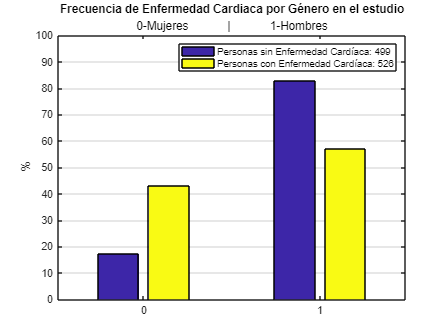

y=[s.Percent(1) e.Percent(1);s.Percent(2) e.Percent(2)];
BarrasGenero=bar(x,y,'FaceColor','flat');
for k = 1:size(y,2)
    BarrasGenero(k).CData = k;
end
ylabel('%')
set(gca,"XGrid","off","YGrid","on")
title("Frecuencia de Enfermedad Cardiaca por Género en el estudio","0-Mujeres            |            1-Hombres");
clear ylim
ylim([0 100])
legend(["Personas sin Enfermedad Cardíaca: 499","Personas con Enfermedad Cardíaca: 526"])

fig01=figure;
hold on
h1 = gplotmatrix(xVar,yVar,valGenero,colors,'.s',10)

h1 =   3×3×2 Line array.


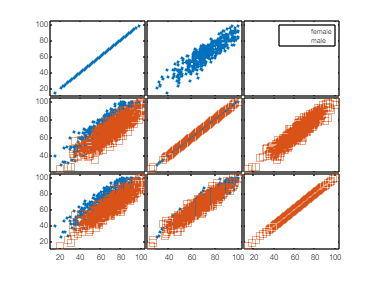

hold off

fig02 = figure;
hold on
h2 = gplotmatrix(xVar,yVar,valRaza,colors,'.*x^',5)

h2 =   3×3×5 Line array.


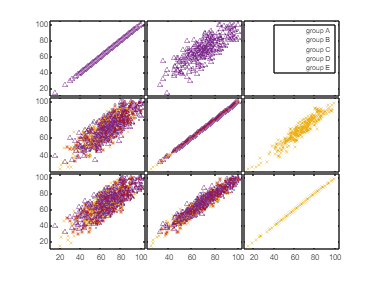

hold off

fig03 = figure;
hold on
h3 = gplotmatrix(xVar,yVar,valPadres,colors,'.*x^',5)

h3 =   3×3×6 Line array.


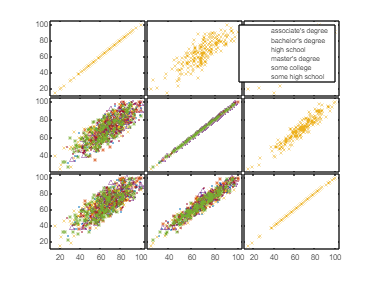

hold off


fig04 = figure;
hold on
h4 = gplotmatrix(xVar,yVar,valDesayuno,colors,'.*x^',5)

h4 =   3×3×2 Line array.


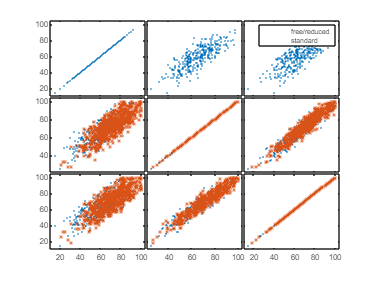

hold off


fig05 = figure;
hold on
h5 = gplotmatrix(xVar,yVar,valPrecurso,colors,'.*x^',5)

h5 =   3×3×2 Line array.


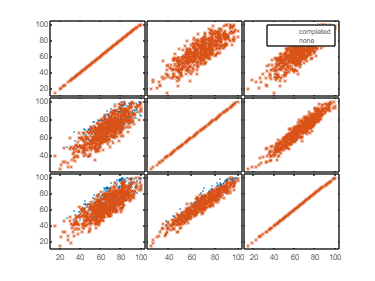

hold off

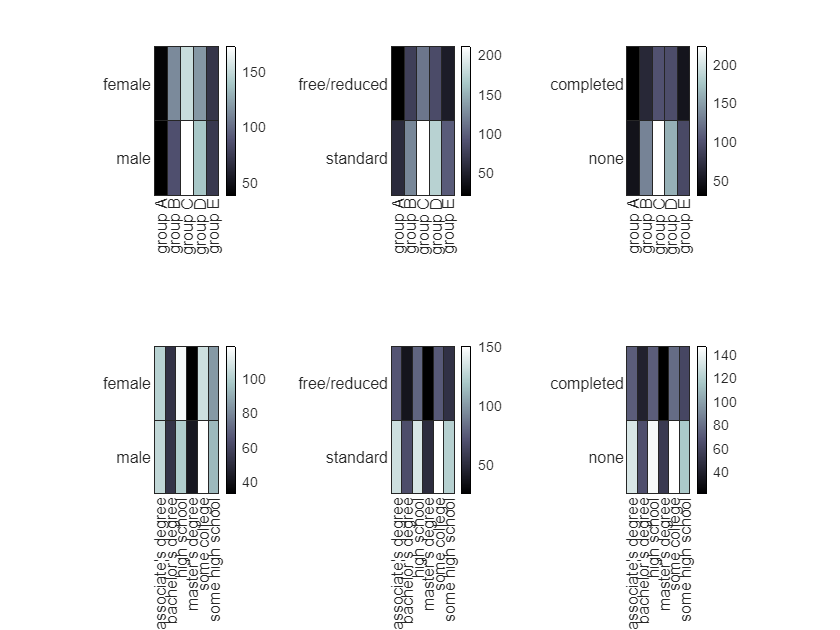

%Variables categoricas
%valGenero 2cat
%valRaza 5cat
%valPadres 5cat
%valDesayuno 2cat
%valPrecurso 2cat
%%%
%Etiquetas de variables
%labelsGenero
%labelsRaza
%labelsPadres
%labelsDesayuno
%labelsPrecurso
%%%
%Variables numéricas
%math
%reading
%writing

cts1 = crosstab(valGenero,valRaza);
cts2 = crosstab(valDesayuno,valRaza);
cts3 = crosstab(valPrecurso,valRaza);
cts4 = crosstab(valGenero,valPadres);
cts5 = crosstab(valDesayuno,valPadres);
cts6 = crosstab(valPrecurso,valPadres);

fig06=figure;
subplot(2,3,1)
    h1 = heatmap(labelsRaza,labelsGenero,cts1,'Colormap',bone);

subplot(2,3,2)
    h2 = heatmap(labelsRaza,labelsDesayuno,cts2,'Colormap',bone);
    %sortx(h2,'male')

subplot(2,3,3)
    h3 = heatmap(labelsRaza,labelsPrecurso,cts3,'Colormap',bone);
    %sortx(h3,'male')

subplot(2,3,4)
    h4 = heatmap(labelsPadres,labelsGenero,cts4,'Colormap',bone);
    %sortx(h4,'male')
subplot(2,3,5)
    h5 = heatmap(labelsPadres,labelsDesayuno,cts5,'Colormap',bone);
    %sortx(h5,'male')
subplot(2,3,6)
    h6 = heatmap(labelsPadres,labelsPrecurso,cts6,'Colormap',bone);

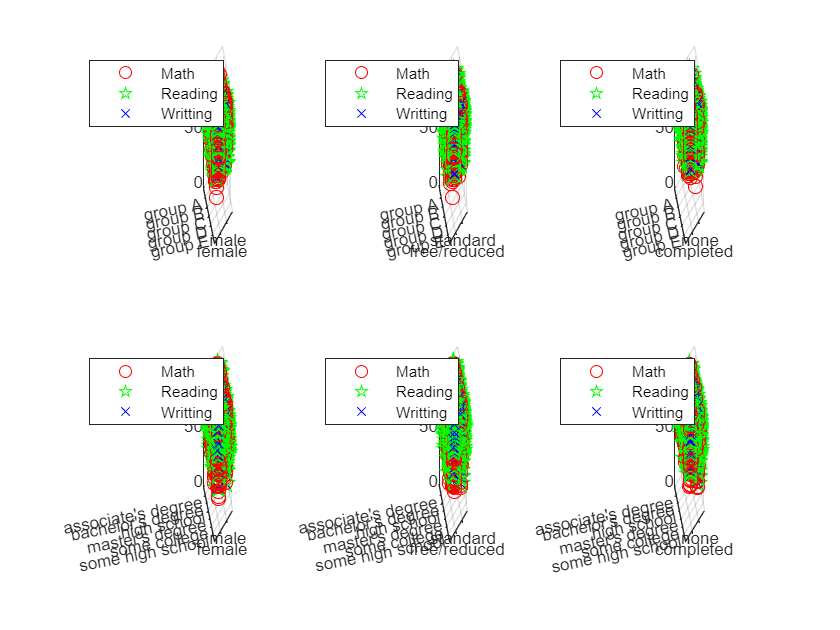

fig07 = figure;
subplot(2,3,1)
hold on
    x  = valRaza;
    y  = valGenero;
    zM = math;
    zR = reading;
    zW = writing;
    swarmchart3(x,y,zM,50,'red','o')
    swarmchart3(x,y,zR,100,'green','pentagram')
    swarmchart3(x,y,zR,50,'blue','x')
    grid on
    legend('Math','Reading','Writting')
    view([60 30])
hold off

subplot(2,3,2)
hold on
    x  = valRaza;
    y  = valDesayuno;
    zM = math;
    zR = reading;
    zW = writing;
    swarmchart3(x,y,zM,50,'red','o')
    swarmchart3(x,y,zR,100,'green','pentagram')
    swarmchart3(x,y,zR,50,'blue','x')
    grid on
    legend('Math','Reading','Writting')
    view([60 30])
hold off
subplot(2,3,3)
hold on
    x  = valRaza;
    y  = valPrecurso;
    zM = math;
    zR = reading;
    zW = writing;
    swarmchart3(x,y,zM,50,'red','o')
    swarmchart3(x,y,zR,100,'green','pentagram')
    swarmchart3(x,y,zR,50,'blue','x')
    grid on
    legend('Math','Reading','Writting')
    view([60 30])
hold off
subplot(2,3,4)
hold on
    x  = valPadres;
    y  = valGenero;
    zM = math;
    zR = reading;
    zW = writing;
    swarmchart3(x,y,zM,50,'red','o')
    swarmchart3(x,y,zR,100,'green','pentagram')
    swarmchart3(x,y,zR,50,'blue','x')
    grid on
    legend('Math','Reading','Writting')
    view([60 30])
hold off

subplot(2,3,5)
hold on
    x  = valPadres;
    y  = valDesayuno;
    zM = math;
    zR = reading;
    zW = writing;
    swarmchart3(x,y,zM,50,'red','o')
    swarmchart3(x,y,zR,100,'green','pentagram')
    swarmchart3(x,y,zR,50,'blue','x')
    grid on
    legend('Math','Reading','Writting')
    view([60 30])
hold off
subplot(2,3,6)
hold on
    x  = valPadres;
    y  = valPrecurso;
    zM = math;
    zR = reading;
    zW = writing;
    swarmchart3(x,y,zM,50,'red','o')
    swarmchart3(x,y,zR,100,'green','pentagram')
    swarmchart3(x,y,zR,50,'blue','x')
    grid on
    legend('Math','Reading','Writting')
    view([60 30])
hold off

%Tablas
%dsStudents_1
%Variables categoricas
%valGenero 2cat
%valRaza 5cat
%valPadres 5cat
%valDesayuno 2cat
%valPrecurso 2cat
%%%
%Etiquetas de variables
%labelsGenero
%labelsRaza
%labelsPadres
%labelsDesayuno
%labelsPrecurso
%%%
%Variables numéricas
%math
%reading
%writing

mathAE    = [dsStudents_1.mathScore(valRaza == 'group B');      dsStudents_1.mathScore(valRaza == 'group C');dsStudents_1.mathScore(valRaza == 'group D')];
readingAE = [dsStudents_1.readingScore(valRaza == 'group B');dsStudents_1.readingScore(valRaza == 'group C');dsStudents_1.readingScore(valRaza == 'group D')];
writingAE = [dsStudents_1.writingScore(valRaza == 'group B');dsStudents_1.writingScore(valRaza == 'group C');dsStudents_1.writingScore(valRaza == 'group D')];

generoAE  = [dsStudents_1.gender(valRaza == 'group B'); dsStudents_1.gender(valRaza == 'group C'); dsStudents_1.gender(valRaza == 'group D')];
pruebaAE  = [dsStudents_1.testPreparation(valRaza == 'group B'); dsStudents_1.testPreparation(valRaza == 'group C'); dsStudents_1.testPreparation(valRaza == 'group D')];
desayunoAE  = [dsStudents_1.lunch(valRaza == 'group B'); dsStudents_1.lunch(valRaza == 'group C'); dsStudents_1.lunch(valRaza == 'group D')];
tableDataVF = table(generoAE,pruebaAE,desayunoAE,mathAE,readingAE,writingAE)

tableDataVF = 778×6 table
    generoAE    pruebaAE      desayunoAE     mathAE    readingAE    writingAE
    ________    _________    ____________    ______    _________    _________
     male       none         free/reduced      70         70           63    
     female     none         standard          46         61           58    
     male       none         standard          74         69           69    
     male       none         standard          53         50           49    
     male       none         free/reduced      76         74           76    
     female     none         standard          70         71           71    
     male       none         standard          74         83           72    
     female     completed    standard          80         81        

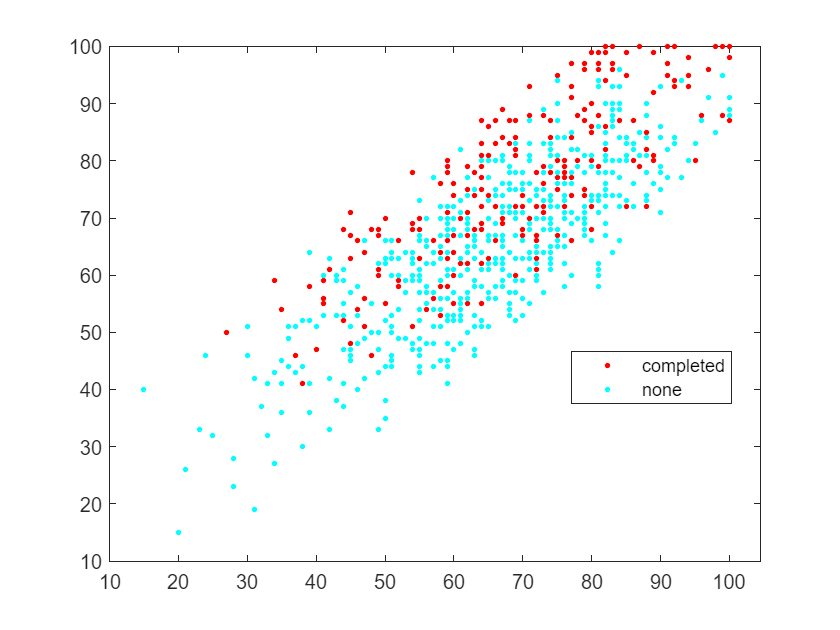

fig09=figure;
gscatter(tableDataVF.mathAE,tableDataVF.writingAE,tableDataVF.pruebaAE)

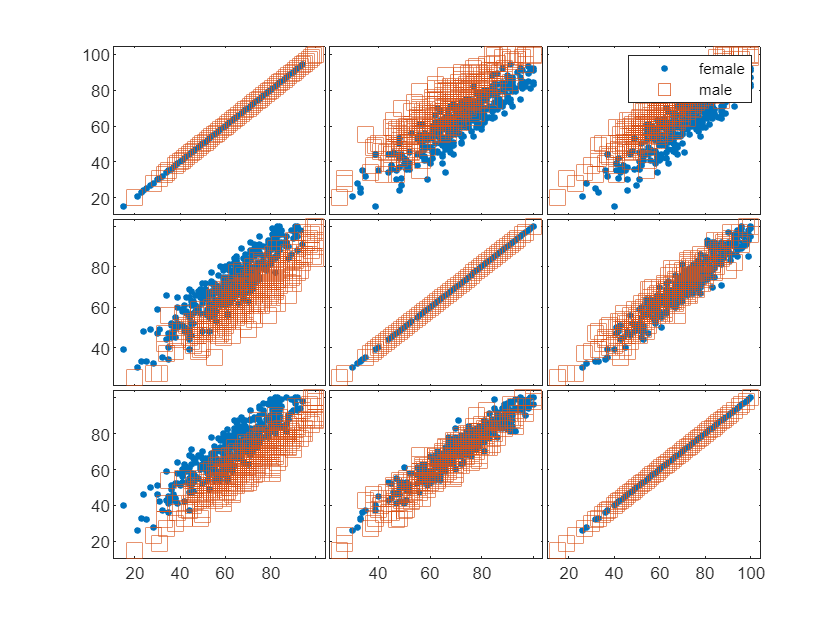

valGenero = tableDataVF.generoAE;
xVar = [mathAE, readingAE, writingAE];
yVar = [mathAE, readingAE, writingAE];
xnames = {'math';'reading';'writing'};
fig09=figure;
gplotmatrix(xVar,yVar,valGenero,colors,'.s',10)

XTotal=[tableDataVF.mathAE, tableDataVF.readingAE];
tam = size(XTotal,1);
PD = 0.3;
index = cvpartition(tam,'holdout',PD)

index = Hold-out cross validation partition
   NumObservations: 778
       NumTestSets: 1
         TrainSize: 545
          TestSize: 233

pTrain = XTotal(index.training, :);
pTest = XTotal(index.test, :);
size(pTrain)

ans =    545     2


size(pTest)

ans =    233     2


X=pTrain;

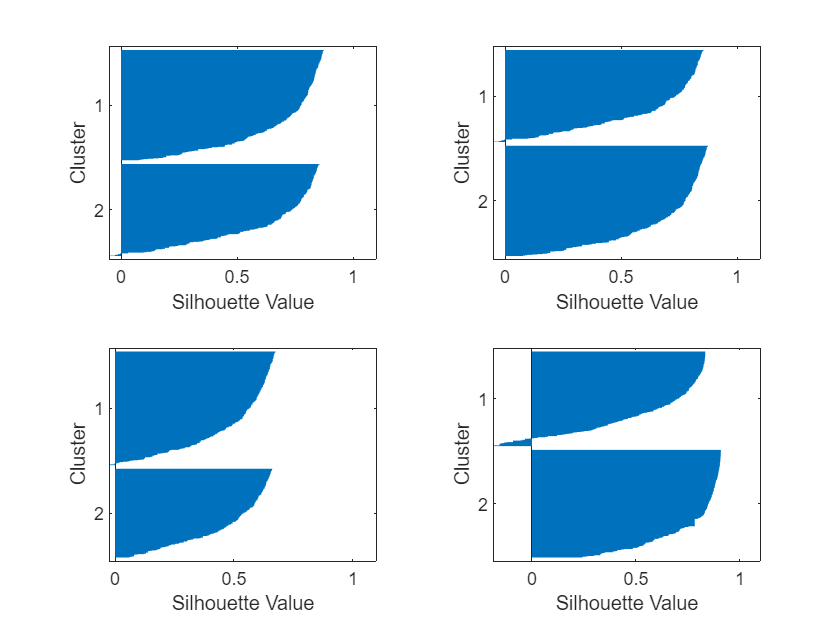

%X=[tableDataVF.mathAE, tableDataVF.readingAE];
%cat = [tableDataVF.generoAE];
%
num = 2;
[grp,C] = kmeans(X,2);
%eva = evalclusters(X,"kmeans","silhouette",...
%    "KList",2,"Distance","cosine")
%num = eva.OptimalK
[grp1,C1] = kmeans(X,num,"Distance","sqeuclidean");
[grp2,C2] = kmeans(X,num,"Distance","cityblock");
[grp3,C3] = kmeans(X,num,"Distance","cosine");
%[grp4,C4] = kmeans(X,2,"Distance","correlation");
%[grp5,C5] = kmeans(X,2,"Distance","hamming");

fig10a=figure;
tiledlayout(2,2);
nexttile
    axis square
    title('Automatico')
    silhouette(X,grp)
nexttile
    axis square
    title('sqeuclidean')
    silhouette(X,grp1,"sqEuclidean")
nexttile
    axis square
    title('cityblock')
    silhouette(X,grp2,"cityblock")
nexttile
    axis square
    title('cosine')
    silhouette(X,grp3,"cosine")

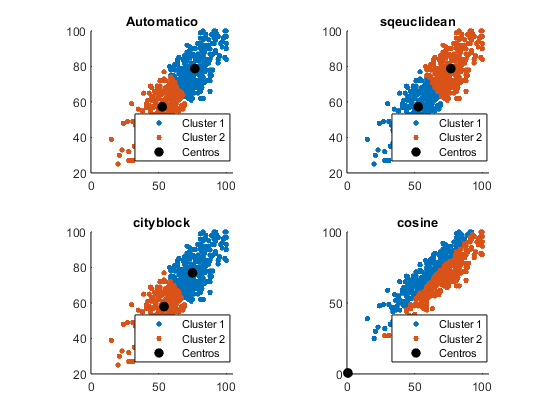

fig10b=figure;
tiledlayout(2,2);
nexttile
hold on
    axis square
    title('Automatico')
    gscatter(X(:,1),X(:,2),grp,colors)
    plot(C(:,1),C(:,2),'.k','MarkerSize',25)
    legend('Cluster 1','Cluster 2','Centros')
hold off
nexttile
hold on
    axis square
    title('sqeuclidean')
    gscatter(X(:,1),X(:,2),grp1,colors)
    plot(C1(:,1),C1(:,2),'.k','MarkerSize',25)
    legend('Cluster 1','Cluster 2','Centros')
hold off
nexttile
hold on
    axis square
    title('cityblock')
    gscatter(X(:,1),X(:,2),grp2,colors)
    plot(C2(:,1),C2(:,2),'.k','MarkerSize',25)
    legend('Cluster 1','Cluster 2','Centros')
hold off
nexttile
hold on
    axis square
    title('cosine')
    gscatter(X(:,1),X(:,2),grp3,colors)
    plot(C3(:,1),C3(:,2),'.k','MarkerSize',25)
    legend('Cluster 1','Cluster 2','Centros')
hold off

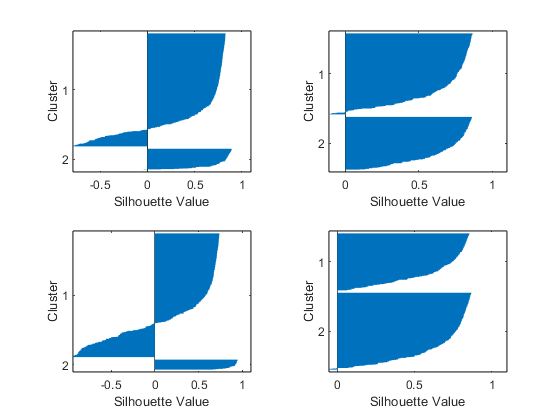

mdl = fitgmdist(X,2,...
                   'RegularizationValue',0.1,...
                   'CovarianceType','full',...
                   'SharedCovariance',true,...
                   'MaxIter',1000);
mdl1 = fitgmdist(X,2,...
                   'RegularizationValue',0.1,...
                   'CovarianceType','diagonal',...
                   'SharedCovariance',true,...
                   'MaxIter',1000);
mdl2 = fitgmdist(X,2,...
                   'RegularizationValue',0.1,...
                   'CovarianceType','full',...
                   'SharedCovariance',false,...
                   'MaxIter',1000);
mdl3 = fitgmdist(X,2,...
                   'RegularizationValue',0.1,...
                   'CovarianceType','diagonal',...
                   'SharedCovariance',false,...
                   'MaxIter',1000);



%mdl1 = fitgmdist(X,2,'RegularizationValue',0.1,"CovarianceType","diagonal","Replicates",5);
%threshold = [0.49 0.51];
%P = posterior(mdl,X);
%n = size(X,1);
%[~,order] = sort(P(:,1));
%figure
%plot(1:n,P(order,1),'r-',1:n,P(order,2),'b-')
%legend({'Cluster 1', 'Cluster 2'})
%idx = cluster(mdl,X);
%idxBoth = find(P(:,1)>=threshold(1) & P(:,1)<=threshold(2)); 
%numInBoth = numel(idxBoth)
%figure
%gscatter(X(:,1),X(:,2),idx,'rb','+o',5)
%hold on
%plot(X(idxBoth,1),X(idxBoth,2),'ko','MarkerSize',10)

grp = cluster(mdl,X);
grp1 = cluster(mdl1,X);
grp2 = cluster(mdl2,X);
grp3 = cluster(mdl3,X);

fig11a=figure;
tiledlayout(2,2);
nexttile
    axis square
    silhouette(X,grp)

nexttile
    axis square
    silhouette(X,grp1)
nexttile
    axis square
    silhouette(X,grp2)
nexttile
    axis square
    silhouette(X,grp3)

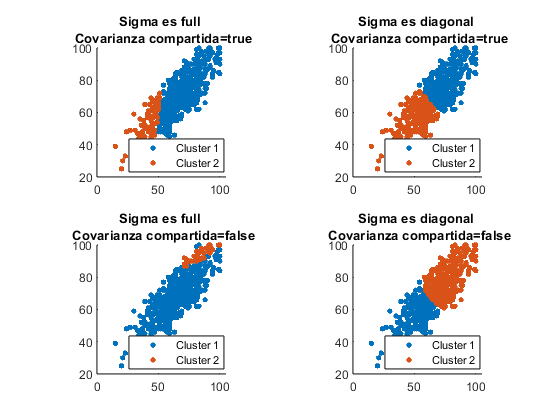


fig11b=figure;
tiledlayout(2,2);
nexttile
hold on
    axis square
    title(sprintf('Sigma es full \n Covarianza compartida=true'))
    gscatter(X(:,1),X(:,2),grp,colors)
    legend('Cluster 1','Cluster 2')
hold off
nexttile
hold on
    axis square
    title(sprintf('Sigma es diagonal \n Covarianza compartida=true'))
    gscatter(X(:,1),X(:,2),grp1,colors)
    legend('Cluster 1','Cluster 2')
hold off
nexttile
hold on
    axis square
    title(sprintf('Sigma es full \n Covarianza compartida=false'))
    gscatter(X(:,1),X(:,2),grp2,colors)
    legend('Cluster 1','Cluster 2')
hold off
nexttile
hold on
    axis square
    title(sprintf('Sigma es diagonal \n Covarianza compartida=false'))
    gscatter(X(:,1),X(:,2),grp3,colors)
    legend('Cluster 1','Cluster 2')
hold off

M='cosine';
Z1 = linkage(X);
Z2 = linkage(X,'average',M);
Z3 = linkage(X,'centroid',M);

Z4 = linkage(X,'complete',M);
Z5 = linkage(X,'median',M);

Z6 = linkage(X,'single',M);
Z7 = linkage(X,'ward',M);

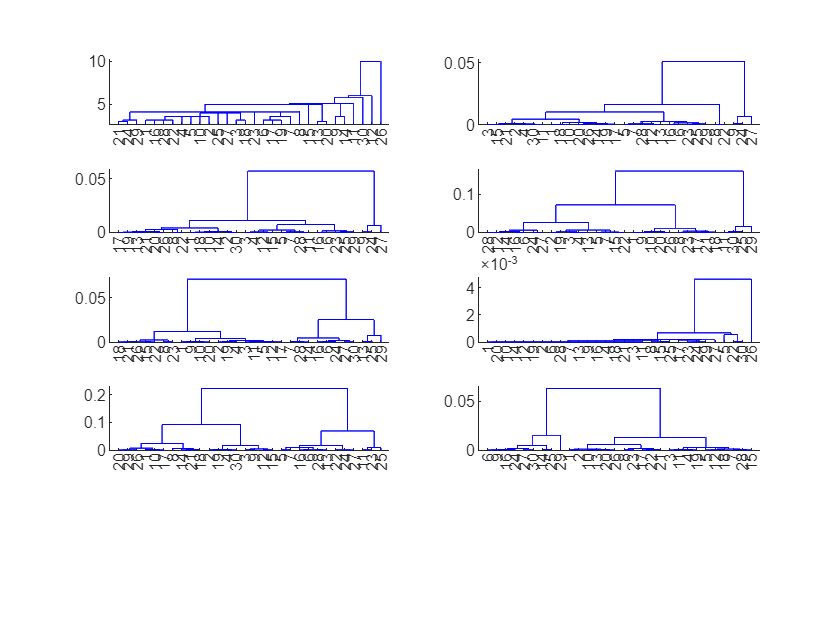

Z8 = linkage(X,'weighted',M);

fig12=figure;
subplot(5,2,1)
    dendrogram(Z1)
subplot(5,2,2)
    dendrogram(Z2)
subplot(5,2,3)
    dendrogram(Z3)
subplot(5,2,4)
    dendrogram(Z4)
subplot(5,2,5)
    dendrogram(Z5)
subplot(5,2,6)
    dendrogram(Z6)
subplot(5,2,7)
    dendrogram(Z7)
subplot(5,2,8)
    dendrogram(Z8)


grp1 = cluster(Z1,'maxclust',2);
D1 = pdist(X);
c1 = cophenet(Z1,D1)

c1 = 0.5752


grp2 = cluster(Z2,'maxclust',2);
D2 = pdist(X);
c2 = cophenet(Z2,D2)

c2 = 0.2305


grp3 = cluster(Z3,'maxclust',2);
D3 = pdist(X);
c3 = cophenet(Z3,D3)

c3 = 0.2138


grp4 = cluster(Z4,'maxclust',2);
D4 = pdist(X);
c4 = cophenet(Z4,D4)

c4 = 0.1583


grp5 = cluster(Z5,'maxclust',2);
D5 = pdist(X);
c5 = cophenet(Z5,D5)

c5 = 0.2129


grp6 = cluster(Z6,'maxclust',2);
D6 = pdist(X);
c6 = cophenet(Z6,D6)

c6 = 0.1645


grp7 = cluster(Z7,'maxclust',2);
D7 = pdist(X);
c7 = cophenet(Z7,D7)

c7 = 0.1830


grp8 = cluster(Z8,'maxclust',2);
D8 = pdist(X);
c8 = cophenet(Z8,D8)

c8 = 0.2170

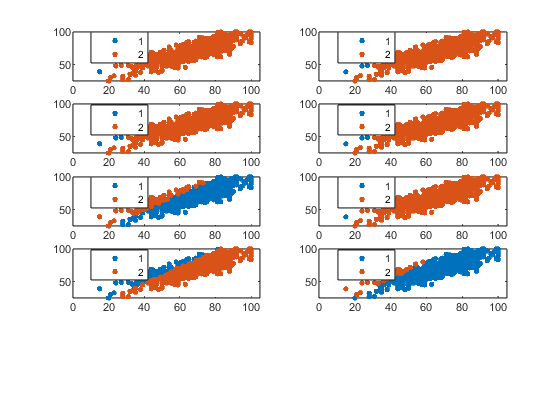



fig13=figure;
subplot(5,2,1)
    gscatter(X(:,1),X(:,2),grp1,colors)
     
subplot(5,2,2)
    gscatter(X(:,1),X(:,2),grp2,colors)
     
subplot(5,2,3)
    gscatter(X(:,1),X(:,2),grp3,colors)
     
subplot(5,2,4)
    gscatter(X(:,1),X(:,2),grp4,colors)
     
subplot(5,2,5)
    gscatter(X(:,1),X(:,2),grp5,colors)

subplot(5,2,6)
    gscatter(X(:,1),X(:,2),grp6,colors)
     
subplot(5,2,7)
    gscatter(X(:,1),X(:,2),grp7,colors)
     
subplot(5,2,8)
    gscatter(X(:,1),X(:,2),grp8,colors)